# Feedback controller design for a SISO system (Fj- Tj)

# based on  Ziegler Nichols with IMC method   

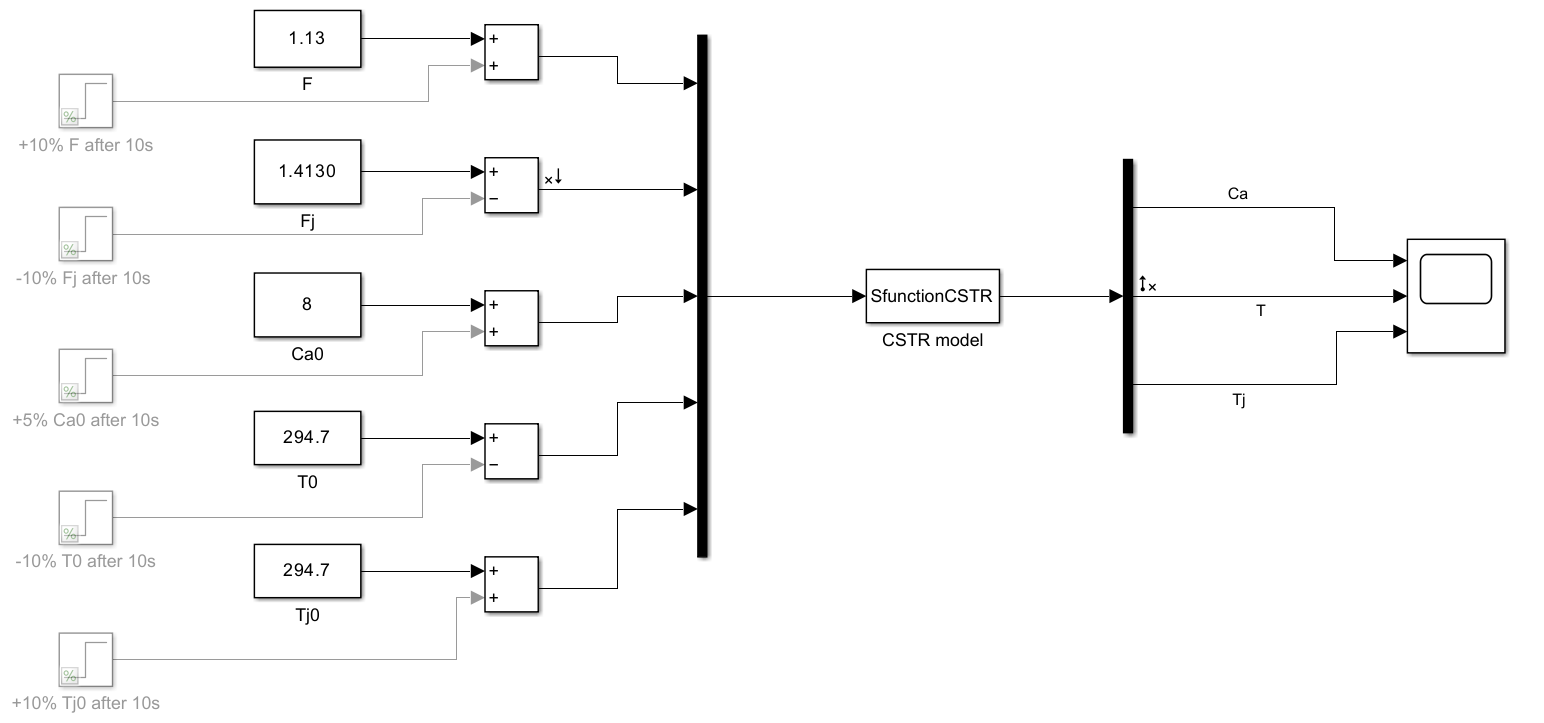

**Given ****: ** **A simulink nonlinear process model  ( CSTR Model)  **

## ** Ziegler Nicols with IMC Method :**

**Ziegler Nichols method is based on  **the assumption that  the required input /output  model is ** a first order transfer  function with time delay  ( or dead time) ( See Lecture-6, Part-I, page 12  ) .**

First of all   one should obtain such a transfer function  (FOPTD- first order plus  time delay)  which approximates  the linear dynamic relationship between input and ouput of our interest.  In this case input is  Fj and output is Tj.

**Steps to follow :**

**1) Linearize the  system  by considering  the particular single input and single output  ** by using the   Model Linearizer tool. 

Obtain the linear state space model data  ( linsys1)  for this particular I/O pair.

Copy  **linsys1** data to the MATLAB Wokspace.

**2) I**t is possible to obtain a transfer function model G  in   "s" domain  based on  linearized system matrices (A,B,C,D)  and 

G0 ( steady state gain matrix) or  based on  state space data  obtained  by the Model  linearizer ( e.g. linsys1) **. **

The Matlab built in function is **tf** . We can use  it as follows : 

Gplant2 = tf(linsys1)

Gplant2 =
 
  From input "Fj" to output "Tj":
  -658.1 s^2 - 2.653e04 s - 8.521e04
  ----------------------------------
   s^3 + 76.97 s^2 + 1565 s + 2775
 
Name: Linearization at model initial condition
Continuous-time transfer function.
Model Properties


In this case  a third* order* transfer function  is generated.  

Approximate this  3rd order Gplant2 as  a ***first order*** transfer function with a **time delay, **Td,   since the  Ziegler- Nichols controller  tuning  method requires that.

**3)** Therefore we will follow another approach . First of all, we  plot the step response  curve for  the output  based on transfer function ,G :

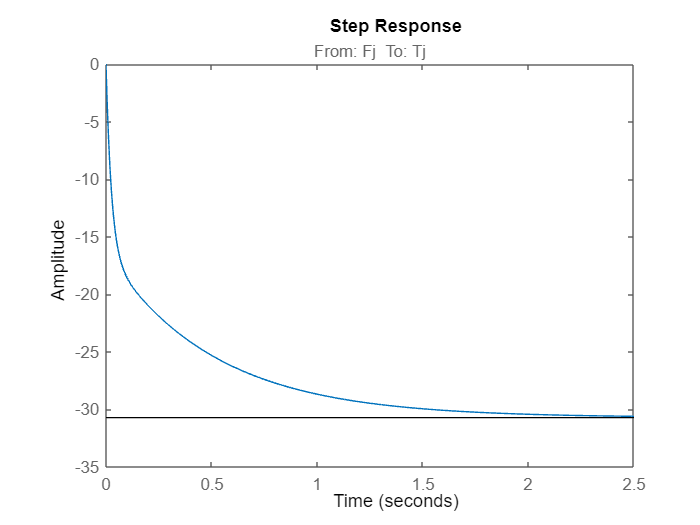

figure(1)
step(Gplant2)

Observe the output response  curve ; it has a slight S-shape. 

**4) **Store  the step response data   as output  variable , y  and time vector , t  . 

The following MATLAB commond  applies a unit step change  in the input and  gets the  output response, y, at each time point :

[y,t] = step(Gplant2);
y=-y;

Plot  the ouput response data  again :

figure(2)
plot(t,y,'k')
title('Process reaction curve')

**5) **Find  parameters** , gain (K), time constant (T)  and  dead time (Td) **which appear in the FOPDT transfer function model .

The following MATLAB script was adopted  from Ravikiran Yalamarthi, who published the his MATLAB  code  in June 2020  on the web pages  of MATLAB file exchange .

(See the hyperlink  :  [Process Reaction Curve](https://de.mathworks.com/matlabcentral/fileexchange/77371-process-reaction-curve)  )

Calculate the slope at each point :

slope = gradient(y,t)

slope =   629.3424
  602.3324
  550.7084
  503.6652
  460.7984
  421.7392
  386.1511
  353.7269
  324.1867
  297.2750


Find out  coordinates of the point of inflection :

[tslope,idx] = max(slope)

tslope = 629.3424

idx = 1

tIP = t(idx)

tIP = 0

yIP = y(idx)

yIP = 0

Estimate  the tangent  line  of the step response curve  at  the inflection point :

yTangentLine = tslope*(t-tIP) + yIP

yTangentLine = 1.0e+03 *

         0
    0.0015
    0.0031
    0.0046
    0.0062
    0.0077
    0.0093
    0.0108
    0.0124
    0.0139


Plot the  inflection point and  the tangent line on step response curve :

hold on
plot(tIP,yIP,'r*'),grid on 
plot(t,yTangentLine,'b')
ylim([0 1])            % zoom-in  in the previous plot 
xlabel( 'time (min)')
ylabel( 'y  ')

Estimate  parameters of the transfer function model (as a first order plus  dead time  -FOPTD model )

Timde delay (Dead time) , Td :

Td = tIP-(yIP/tslope)

Td = 0

 Time constant , Tau : 

Tau1 = y(end)/tslope

Tau1 = 0.0485

Tau1 is less than 0.6087(Tau for Fj and T). Hence we can go on with this method:

Process gain, K :

K = y(end)/1

K = 30.5521

Show the delay time in plot

plot(Td,0,'g.','MarkerSize',15)

Define Approximate transfer function and plot the step response

G1new = tf(K,[Tau1 1],'InputDelay',Td)

G1new =
 
      30.55
  -------------
  0.04855 s + 1
 
Continuous-time transfer function.
Model Properties


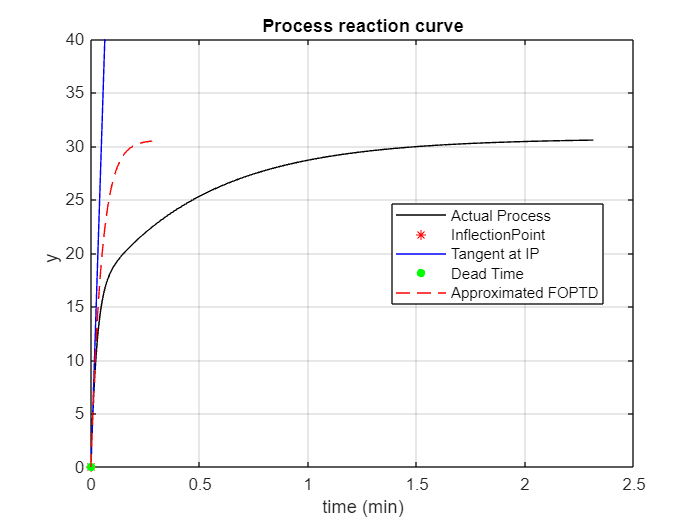

[z,t] = step(G1new);
plot(t,z,'r--'), hold off
legend('Actual Process','InflectionPoint','Tangent at IP','Dead Time', ...
    'Approximated FOPTD','Location','best')

xlim([0.000 2.5])
ylim([0.00 40])

**6)  Calculate the P  conroller parameters :**

Based on the first order  transfer function  parameters , K, T,  (Td)   use  the IMC method (Bequette Table 7-2 )for Kp 

calculation for P controller:

**P  conroller parameters**** :  Kp   **

Get the process gain as original reverse action

K = -K

K = -30.5521

Close loop time constant should be less than process time constant and also greater than 1.7*Td **(Tau > Tc > 1.7*Td)**. Hence assuming it as 1/3 of Tau.

Tc = Tau1/3

Tc = 0.0162

Kp2 = (Tau1)/(K*Tc)

Kp2 = -0.0982

**Calculation of PI Controller Parameters :**

Kp2 = (Tau1)/(K*Tc)

Kp2 = -0.0982

TI2 = Tau1

TI2 = 0.0485

KI2 = 1/TI2

KI2 = 20.5990